# Uncertain Observer Simulation

Author: Jonas Wagner

Date: 2021-12-14

clear
close all

### Simulation Setup

#### Siumulation Settings

% Simulation Timesteps
N = 10;

sysSelect = 4;
alphaSelect = 1;
% IC_Select = 

% Run Tests
testCtrb = false;
testObsv = false;
testK = false;
testL = false;

% Run Sim
runSim = true;
indSim = false;

% Sim Plots



% plotAllResiduals = false;
% plotResidualStatistics = false;
% scatterPlot_x_k = false;
% scatterPlot3D_x_k = false;
% scatterPlot3D_e_k = false;
% scatterPlot_z_k = false;
% scatterPlot3D_z_k = false;
% scatterPlot_z_k_i = false;


#### Simulation Setup

% PolytopicSysDef
[A_all,B,C,D] = PolytopicSysDef(sysSelect);

% System Dimensions
n = size(A_all,1);
m = size(A_all,3);
p = size(B,2);
q = size(C,1);

% Parameter Definition
[alpha_real_all, alpha_hat_all] = PolytopicParamDef(alphaSelect,m)

alpha_real_all =     1.0000         0         0         0    0.2500    0.2951    0.4066    0.3139    0.4014    0.1365    0.2650    0.2639    0.4190    0.2227    0.3480    0.1843    0.1057    0.2932    0.4565    0.4550    0.3397    0.3513    0.0994    0.3484    0.1279    0.1517    0.3380    0.3529    0.2236    0.4100    0.0903    0.0983    0.3495    0.1080    0.2619    0.0577    0.3766    0.1082    0.2500    0.4055    0.3647    0.4778    0.2065    0.3192    0.1966    0.4298    0.0454    0.4704    0.7831    0.2618
         0    1.0000         0         0    0.2500    0.3281    0.0627    0.3163    0.2035    0.2964    0.0144    0.2946    0.1094    0.0371    0.1588    0.1603    0.2769    0.3119    0.1133    0.1614    0.1154    0.3783    0.1715    0.1042    0.1634    0.3585    0.1053    0.5267    0.3282    0.3384    0.4422    0.3573    0.3794    0.4307    0.4847    0.5205    0.4003    0.3331    0.3627    0.2704    0.2659    0.0903    0.2694    0.3341    0.5238    0.2147    0.0621    0.0489  

alpha_hat_all =     0.2500    1.0000         0         0         0    0.2722    0.1291    0.3622    0.2706    0.2131
    0.2500         0    1.0000         0         0    0.1599    0.3458    0.3416    0.1324    0.1610
    0.2500         0         0    1.0000         0    0.3428    0.3225    0.1209    0.4851    0.2148
    0.2500         0         0         0    1.0000    0.2251    0.2026    0.1753    0.1119    0.4110



% Initial Conditions
X_0_mag = eye(n,2) * [1];
X_0_theta = linspace(-pi,pi,20);%[0, pi/4];%, pi/2, 3*pi/4, pi];
X_0 = round(X_0_mag * [cos(X_0_theta); sin(X_0_theta)],2);
X_hat_0 = X_0;

% Inputs
U_0 = [zeros(p,1)];
u_k = @(x,K) zeros(p,1);

### CVX Design

tol = 1e-6;
cvx_clear

#### Controller Design: 

        
$$u_k = K \hat{x}_k$$


cvx_begin sdp quiet
    variable Q(p,n)
    variable P(n,n) symmetric
    maximize(trace(P))
    subject to
        P >= tol*eye(n);
        for i = 1:m
            [P, (A_all(:,:,i)* P + B * Q)';
            (A_all(:,:,i) * P + B * Q) , P] >= 0;
        end
cvx_end

K = Q / P;
% Testing K
if testK
    disp('Testing K Design')
    for i = 1:m
        disp('i = ')
            disp(i)
        disp('A_i =')
            disp(A_all(:,:,i))
        disp('A_i + BK')
            disp(A_all(:,:,i) + B * K)
        disp('eig(A_i + BK')
            disp(eig(A_all(:,:,i) + B * K))
    end
end

#### Observer Design: 

        
$$\hat{x}_{k+1} = \hat{A} \hat{x}_k + B u_k + L (y_k - \hat{y}_k)$$


cvx_begin sdp quiet
    variable X(n,q)
    variable Q(n,n) symmetric
    tol = 1e-6;
    minimize(trace(Q))
    subject to
        for i = 1:m
            Q >= tol*eye(n);
            [Q, (Q*A_all(:,:,i) - X*C)';
             Q*A_all(:,:,i) - X*C, Q] >= tol*eye(2*n);
        end
cvx_end

L = Q \ X

L =     0.1524   -0.1724
    1.1600    0.1907
   -1.6397   -0.6234
    0.2008   -0.1350



% Testing L
if testL
    disp('Testing L Design')
    for i = 1:m
        disp('i = ')
            disp(i)
        disp('A_i = ')
            disp(A_all(:,:,i))
        disp('A_i - LC')
            disp(A_all(:,:,i) - L * C)
        disp('eig(A_i - LC)')
            disp(eig(A_all(:,:,i) - L*C))
        disp('--------------------------')
    end
end

Detector

SigmaInv = eye(q);

## Simulation

% Run Simulation Function (with no input or control)
[results, sim_params] = PolytopicSysSim(...
    A_all, C, L, alpha_real_all, alpha_hat_all, X_0,...
    [], N, B, D, K, U_0,  u_k, SigmaInv);

% results shape: size(results=[sys_real, sys_hat, K, L, X_0, X_hat_0, U_0]

X_0_data = reshape([results.x_0],n,[]);
Z_data = reshape([results.Z],N,[])';
X_data = reshape([results.X]',n,N,[]);

% X_0_data = reshape(cell2mat({results.x_0}), [], n);
% Z_data = reshape(cell2mat({results.Z}), [], N);


% x_0_eqaul_x_hat_0_test = arrayfun(@(a,b) a{:} - b{:},...
%     {results.x_0},{results.x_hat_0},'UniformOutput',false);




## Detector Development

% Predicted Bound
M = DetectorStatCalcMatrix(results, sim_params);
M_data = M(:);


## arg max_{x_0} z_pred

V = cell(numel(M),N);
D = cell(numel(M),N);
lambda_max = cell(numel(M),N);
idx_max = cell(numel(M),N);
X_0_max = cell(numel(M),N);
for k = 1:N
    for i = 1:numel(M)
        [V{i,k}, D{i,k}] = eig(M_data{i}{k});
%         [V{:,k}, D{:,k}] = cellfun(@(M) deal(eig(M{k})), M_data, 'UniformOutput', false);
        [lambda_max{i,k}, idx_max{i,k}] = max(diag(D{i,k}));
        X_0_max{i,k} = V{i,k}(:,idx_max{i,k});
    end
end

X_0_max_theta = cellfun(@(x) {atan2(x(2),x(2))},X_0_max);

% [lambda_max, idx_max] = cellfun()


% 
% 
%     [V, D] = eig(M{k});
%     [lambda_max, idx_max] = max(diag(D));
%     x_0_max = V(:,idx_max);
%     Z_k_max(k) = z_k_x_0(x_0_max,k);
%     X_0_max_theta(k) = atan2(x_0_max(2),x_0_max(1));

## Z_pred

Z_pred = DetectorStatCalc(results, sim_params)

Z_pred = 5-D cell array
Z_pred(:,:,1,1,1) = 

    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}
    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 double}    {1×10 doub

## Z_max

% % Z_max calculated from the 
% Z_max = max(cell2mat(Z_pred(:)),[],1);

sys_poly = struct('A', A_all, 'B', B, 'C', C, 'D', D);

sys_real = PolytopicSysCalc(sys_poly, eye(m));
sys_hat = PolytopicSysCalc(sys_poly,(1/m)*ones(m,1));

M_k = cellfun(@(sys_real) DetectorStatCalcMatrixSingle(sys_real,sys_hat,L,sim_params), sys_real,'UniformOutput',false)';

% % For static A @ alpha=[1,0,...,0]
% M_1_k = M_k{1};%reshape([M_k{1}{:}],[],n,n);
num_M_k = size(M_k,1);


V = cell(N,num_M_k);
D = cell(N,num_M_k);
lambda_max = cell(N,num_M_k);
idx_max = cell(N,num_M_k);
X_0_max = cell(N,num_M_k);
Z_max_all = cell(N,num_M_k);

for k = 1:N
    for i = 1:num_M_k
        [V{k,i}, D{k,i}] = eig(M_k{i}{k});
        [lambda_max{k,i}, idx_max{k,i}] = max(abs(diag(D{k,i})));
        X_0_max{k,i} = V{k,i}(:,idx_max{k,i});
        Z_max_all{k,i} = X_0_max{k,i}' * M_k{i}{k} * X_0_max{k,i};
    end
end
Z_max = max(cell2mat(Z_max_all),[],2)

Z_max =   110.5109
   16.6928
   26.6242
    8.3651
    8.6939
    3.6732
    3.6404
    1.8422
    1.8007
    1.0910


## Detector Test

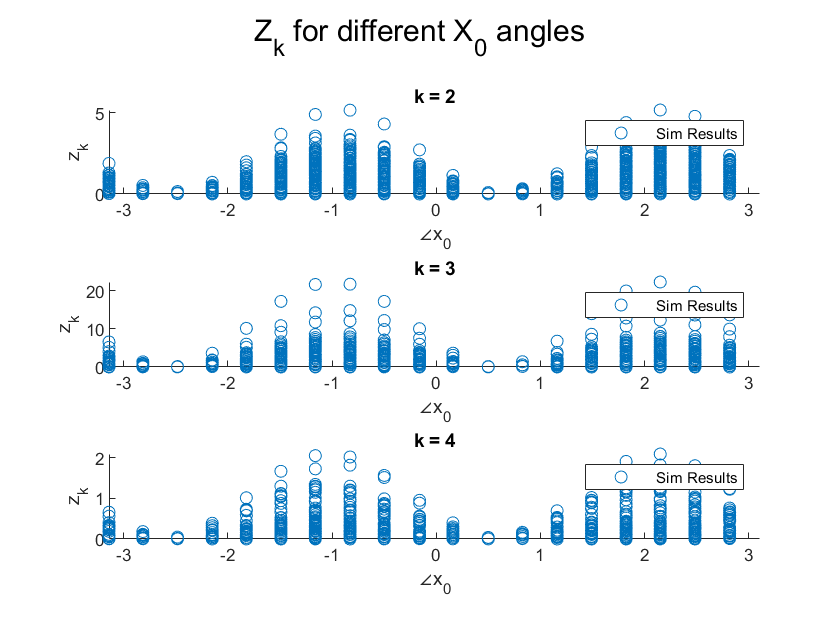


X_0_mag = eye(n,2) * 1;
X_0_theta = -pi:0.25:pi;
X_0 = num2cell(X_0_mag * [cos(X_0_theta); sin(X_0_theta)],1);

% z_k_x_0 = @(x_0, k) x_0'* M{k} * x_0;

% x_0_angle = @(x_0) atan2(x_0(2,:),x_0(1,:));
X_0_angle_data = atan2(X_0_data(2,:),X_0_data(1,:));


% Z_pred

figure()
sgtitle('Z_k for different X_0 angles')
num_plots = 3;
for k = (1:num_plots) + 1 % z_k doesn't work for k=1...
    subplot(num_plots,1,k-1);
    hold on
    title(['k = ', num2str(k)])
    xlabel('\angle{x_0}')
    ylabel('z_k')
    xlim([min(X_0_theta), max(X_0_theta)])
    
    
%     % Visualize M_k for all x_0 (M_k is the first one...)
%     plot(X_0_theta, cellfun(@(x) x'*M_data{1}{k}*x, X_0),...
%         'DisplayName', 'X_0(theta)')
    
    % Z_k Max
    
    
%     [V, D] = eig(M{k});
%     [lambda_max, idx_max] = max(diag(D));
%     x_0_max = V(:,idx_max);
%     Z_k_max(k) = z_k_x_0(x_0_max,k);
%     X_0_max_theta(k) = atan2(x_0_max(2),x_0_max(1));
    
%     % Plot Z_k Bound
%     plot([min(X_0_theta), max(X_0_theta)],...
%          [Z_k_max(k), Z_k_max(k)],...
%          'r',...
%          'DisplayName', 'Z_k Bound')
%     
%     % Z_k Max Location
%     scatter([X_0_max_theta(k)], [Z_k_max(k)],...
%         'g*', ...
%         'DisplayName', 'X_0(MAX)')
%     
    % Sim Results
%     z_k_vals = cellfun(@(z_k) z_k(:,k), Z_data);
    scatter(X_0_angle_data', Z_data(:,k),...
        'DisplayName', 'Sim Results')
    legend()
end

## Plots and Visualization

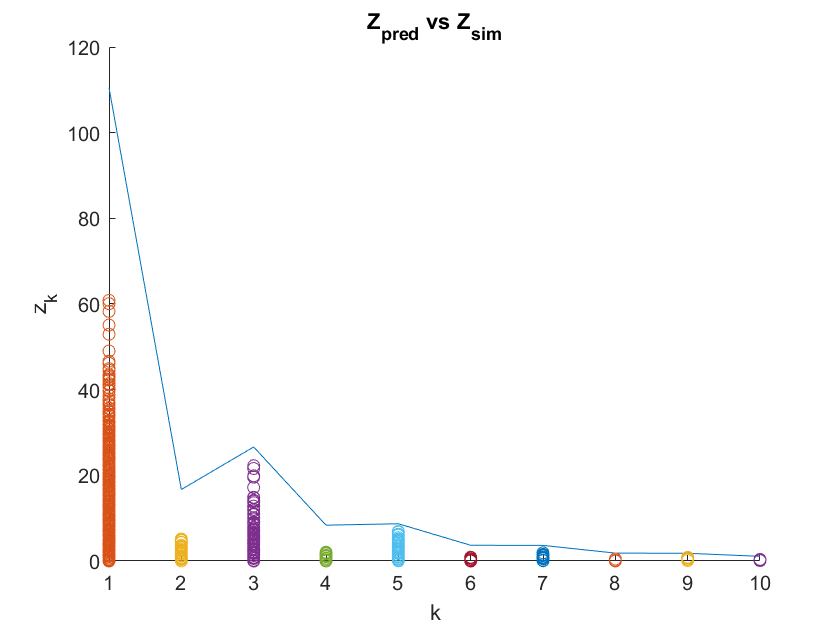

figure()
hold on
plot(Z_max);
for k = 1:N
    scatter(k.*ones(size(Z_data,1),1), Z_data(:,k))
end
title('Z_{pred} vs Z_{sim}')
xlabel('k')
ylabel('z_k')

## Testing